# Sistemi LTI: misura di risposta al gradino 

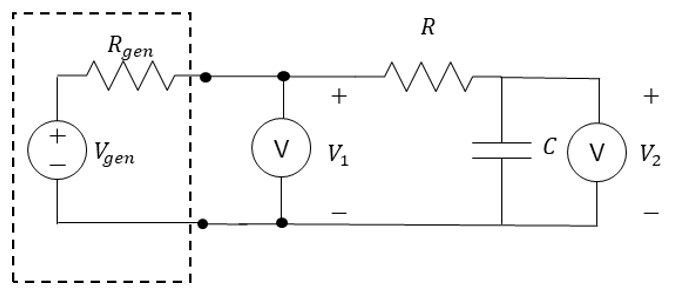

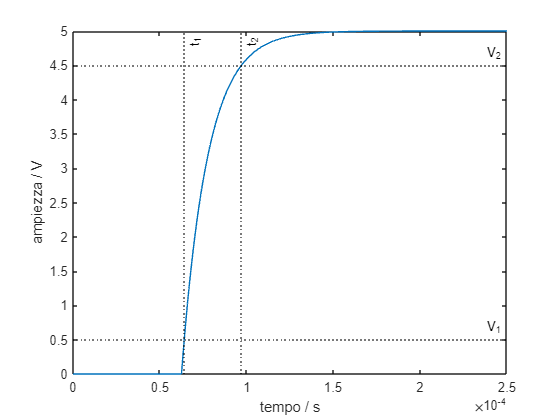

## Simulazione di risposta al gradino

% Si simuli la risposta al gradino per il circuito in figura, e si misuri il tempo di salita
% Produrre anche un grafico come quello in figura, 
% con evidenziati gli istanti t1 e t2, e le tensioni V1 e V2

% Dati
% R = 1e2; % resistenza / ohm
% C = 100e-9; % capacità / F
% s = tf('s') % variabile della trasformata di Laplace
% Td = 25e-5 % durata della simulazione
% N = 1e4; % numero di campioni
% t0 = Td/4; % istante di tempo del gradino / s
% V0 = 5; ampiezza del gradino / V

% Domande
% Rgen = resistenza del generatore
% tau = costante di tempo del sistema, ai fini della risposta al gradino
% fc = frequenza di taglio del sistema, ai fini della risposta al gradino
% H_tf = funzione di trasferimento
% t = vettore colonna di N istanti di tempo equispaziati in [0; Td[
% x = segnale a gradino nell'istante t0
% y = risposta al segnale x
% t1 = primo istante dell'intervallo del tempo di salita
% t2 = secondo istante dell'intervallo del tempo di salita
% V1 = tensione dell'istante t1 del tempo di salita
% V2 = tensione dell'istante t2 del tempo di salita
% tr = tempo di salita


% Codice iniziale
clear

R = 1e2; % resistenza
C = 100e-9; % capacità
s = tf('s') % variabile della trasformata di Laplace

s =
 
  s
 
Continuous-time transfer function.




Td = 25e-5

Td = 2.5000e-04

N = 1e6;
t0 = Td/4;
V0 = 5;

### Soluzione

Rgen = 50

Rgen = 50

R1 = R + Rgen %resistenza serie

R1 = 150

tau = R1*C

tau = 1.5000e-05

fc = 1/2*pi*tau

fc = 2.3562e-05

H_tf = 1/(1+s*tau)

H_tf =
 
        1
  -------------
  1.5e-05 s + 1
 
Continuous-time transfer function.



Ts = Td/N %periodo di campionamento

Ts = 2.5000e-10

n = (0:N-1)'; %vettore colonna degli indici
t = n*Ts %istanti di campionamento

t = 	1.0e+-3 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


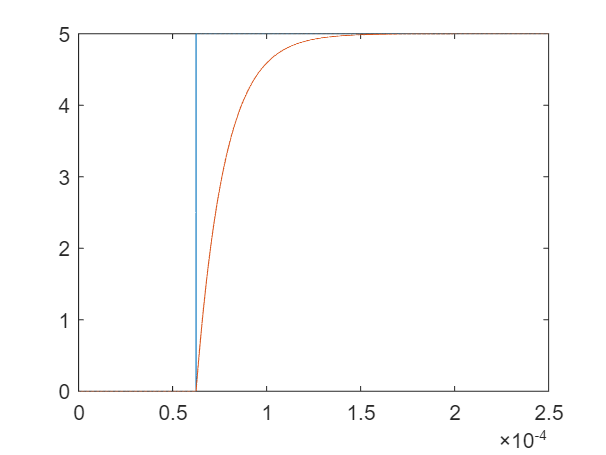

x = V0*heaviside(t-t0); %segnale di ingresso
y = lsim(H_tf,x,t); %segnale di uscita: simulazione di Y(s) = H_tf(s)*X(s)
plot(t,x,t,y)

V1 = 0.1*V0

V1 = 0.5000

V2 = 0.9*V0

V2 = 4.5000

t1 = t0 - tau*log(0.9)

t1 = 6.4080e-05

t2 = t0 - tau*log(0.1)

t2 = 9.7039e-05

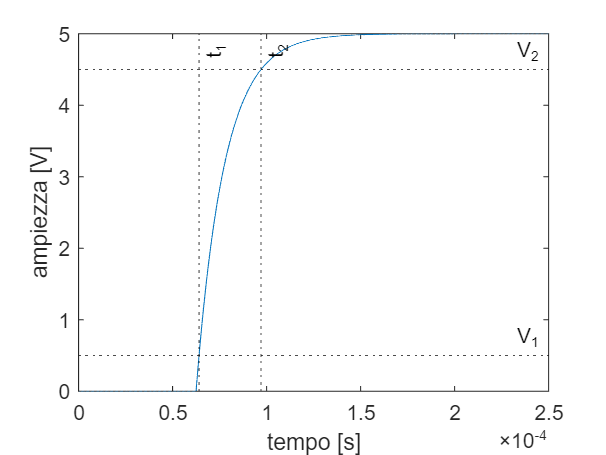

plot(t,y)
xline([t1,t2], ':k',{'t_1','t_2'})
yline([V1,V2], ':k',{'V_1','V_2'})
xlabel('tempo [s]')
ylabel('ampiezza [V]')

tr = t2-t1
tr = tau*log(9) %formula diretta

## Misura di tempo di salita da risposta al gradino misurata senza errori

## 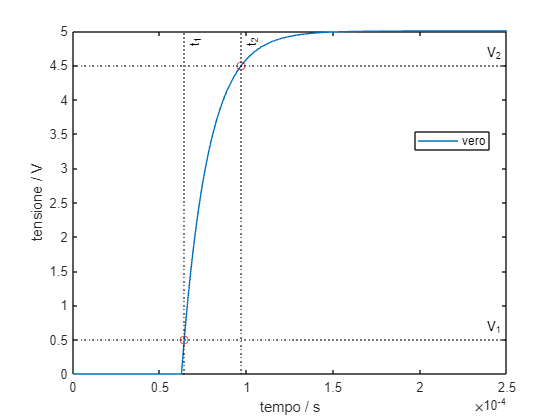

% Per il circuito del quesito precedente, è stata misurata la risposta al gradino in figura.
% Misurare il tempo di salita dai campioni del segnale.
% Si dispone della risposta vera (senza errori).
% Produrre anche un grafico della risposta come in figura, con evidenziati t1, t2, V1, V2.

% Dati
% t = vettore colonna degli istanti di tempo
% y = risposta vera
% V0 = 5 ampiezza del segnale vero / V
% tr0 = tempo di salita vero

% Domande
% V1 = livello di tensione 1 per la misura di tempo di salita
% V2 = livello di tensione 2 per la misura di tempo di salita
% t1 = istante 1, inizio del tempo di salita
% t2 = istante 2, fine del tempo di salita
% tr = tempo di salita
% er_ppm = errore relativo in ppm nella misura tr, assumendo come riferimento tr0

% Codice iniziale
tr0 = tau*log(9)% tempo di salita vero

tr0 = 3.2958e-05

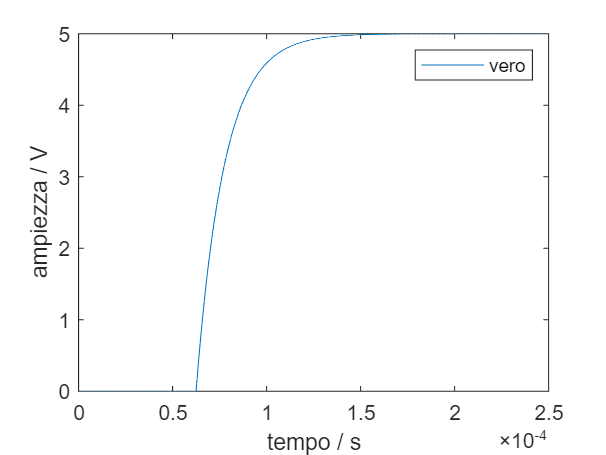

% erG = 0.2 % errore di guadagno dello strumento di misura, pari al 20%
% eO = -15/100*V0; % errore di offset dello strumento di misura, pari a -15% di V0
% 
% ymis = y*(1+erG)+eO; % segnale misurato con errori di offset e di guadagno

plot(t,y)
xlabel('tempo / s')
ylabel('ampiezza / V')
legend('vero')

### Soluzione

V1 = 0.1*V0

V1 = 0.5000

V2 = 0.9*V0

V2 = 4.5000

%ricerca degli istanti di tempo
[dummy, i1] = min(abs(V1-y))

dummy = 2.7679e-05

i1 = 256323

t1 = t(i1)

t1 = 6.4081e-05

[dummy, i2] = min(abs(V2-y))

dummy = 8.7984e-07

i2 = 388156

t2 = t(i2)

t2 = 9.7039e-05

tr = t2-t1

tr = 3.2958e-05

er_ppm = (tr/tr0-1)*1e6

er_ppm = -3.6003

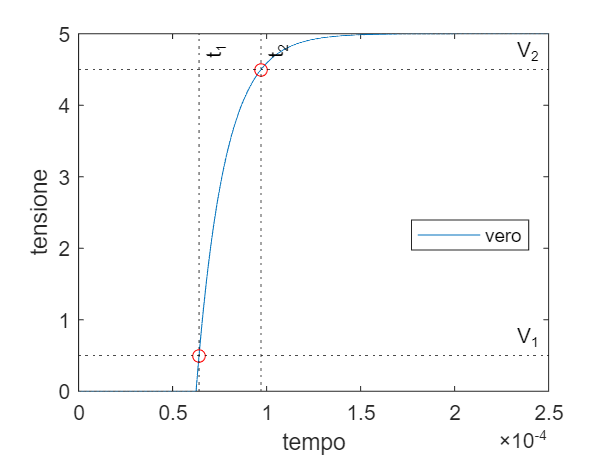

plot(t,y,t1,y(i1),'or',t2,y(i2),'or')
xlabel('tempo')
ylabel('tensione')
xline([t1,t2],':k',{'t_1','t_2'})
yline([V1,V2],':k',{'V_1','V_2'})
legend('vero','location','best')

## Misura di tempo di salita da risposta al gradino misurata con errori di guadagno e offset

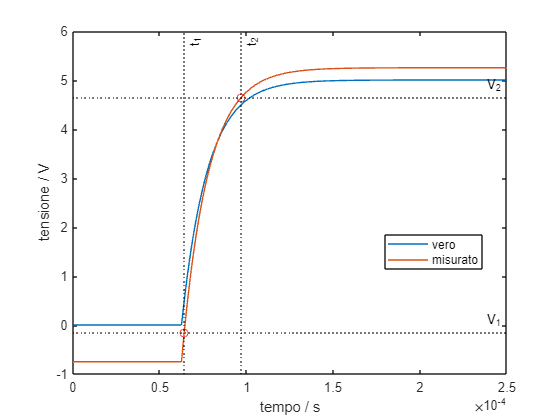

% Per il circuito del quesito precedente, è stata misurata la risposta al gradino in figura.
% Misurare il tempo di salita dai campioni del segnale.
% Si tenga conto che il segnale è misurato con errore di guadagno e di offset, cioè, detto y 
% il segnale vero:
%
% ymis = (1+erG)*y + eO
%
% dove erG (adimensionale) è l'errore relativo di guadagno, mentre eO (volt) è l'errore di offset.
%
% Produrre anche un grafico della risposta come in figura, con evidenziati t1, t2, V1, V2.

% Dati
% t = vettore colonna degli istanti di tempo
% ymis = risposta misurata
% tr0 = tempo di salita vero

% Domande
% V1 = livello di tensione 1 per la misura di tempo di salita
% V2 = livello di tensione 2 per la misura di tempo di salita
% t1 = istante 1, inizio del tempo di salita
% t2 = istante 2, fine del tempo di salita
% tr = tempo di salita
% er_ppm = errore relativo in ppm nella misura tr, assumendo come riferimento tr0

% Codice iniziale
tr0 = tau*log(9)% tempo di salita vero

tr0 = 3.2958e-05

erG = 0.2 % errore di guadagno dello strumento di misura, pari a +20%

erG = 0.2000

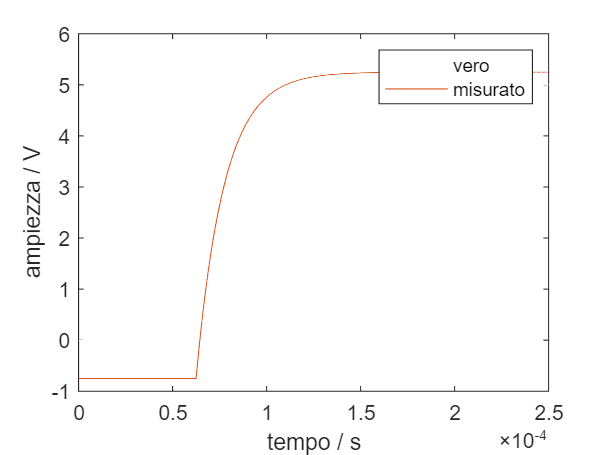

eO = -15/100*V0; % errore di offset dello strumento di misura, pari a -15% di V0

ymis = y*(1+erG)+eO; % segnale misurato con errori di offset e di guadagno

plot(t,y,'w',t,ymis)
xlabel('tempo / s')
ylabel('ampiezza / V')
legend('vero','misurato')

### Soluzione

Vbase = ymis(1)

Vbase = -0.7500

Vtop = ymis(end)

Vtop = 5.2500

Vpp = Vtop - Vbase

Vpp = 6.0000

V1 = Vbase + 0.1*Vpp

V1 = -0.1500

V2 = Vbase + 0.9*Vpp

V2 = 4.6500


[dummy, i1] = min(abs(V1-ymis))

dummy = 3.5451e-05

i1 = 256323

t1 = t(i1)

t1 = 6.4081e-05

[dummy, i2] = min(abs(V2-ymis))

dummy = 9.3193e-07

i2 = 388154

t2 = t(i2)

t2 = 9.7038e-05

tr = t2-t1

tr = 3.2958e-05

er_ppm = (tr/tr0-1)*1e6

er_ppm = -18.7710

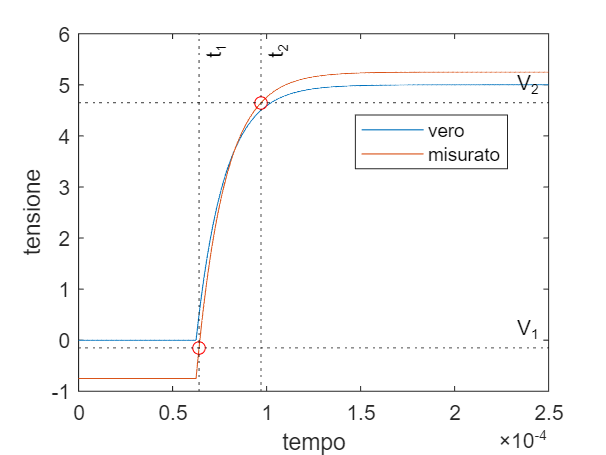

plot(t,y,t,ymis,t1,ymis(i1),'or',t2,ymis(i2),'or')
xlabel('tempo')
ylabel('tensione')
xline([t1,t2],':k',{'t_1','t_2'})
yline([V1,V2],':k',{'V_1','V_2'})
legend('vero','misurato','location','best')

## Misura di frequenza di taglio e di capacità da tempo di salita

% Utilizzando la misura precedente di tempo di salita, misurare frequenza di taglio e capacità nel
% circuito RC

% Dati
% tr = tempo di salita / s
% R = resistenza circuito / ohm
% C0 = capacità vera

% Domande
% Rgen = resistenza del generatore / ohm
% tau = costante di tempo / s
% fc = frequenza di taglio / Hz
% C = capacità / F
% er_ppm = errore relativo in ppm nella misura di capacità, assumendo come riferimento C0

% Codice iniziale
R = 1e2; % resistenza
C0 = 100e-9; % capacità

### Soluzione

Rgen = 50

Rgen = 50

tau = tr/log(9)

tau = 1.5000e-05

fc = 1/(2*pi*tau)

fc = 1.0611e+04

C = tau/(R+Rgen)

C = 9.9998e-08

er_ppm = (C/C0-1)*1e6

er_ppm = -18.7710

## Generazione di onde quadre bipolari e unipolari

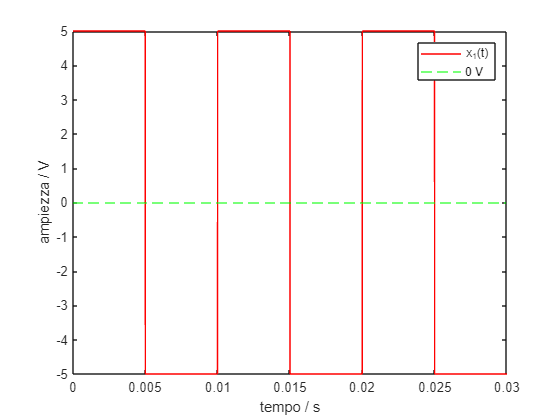

Onda quadra bipolare, tra -V0 e V0, con valore iniziale = +V0

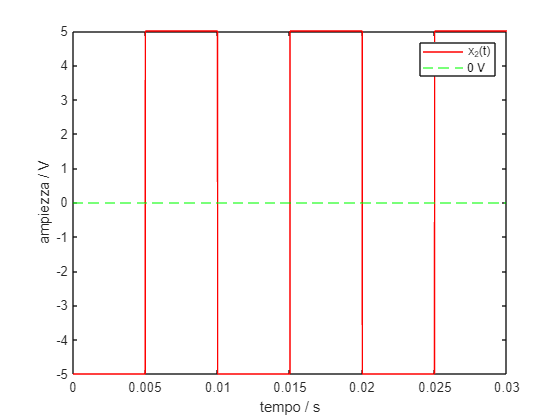

Onda quadra bipolare, tra -V0 e V0, con valore iniziale = -V0

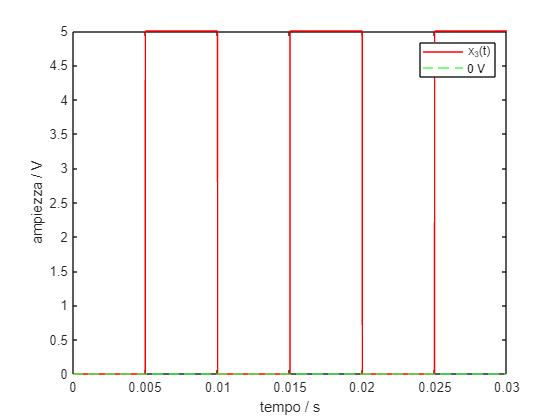

Onda quadra unipolare tra 0 e V0, con valore iniziale = 0

% Generare onde quadre come quelle in figura

% Dati
% V0 = 5 % ampiezza / V
% fx = 100 % frequenza / Hz
% N = 1e5 % numero di campioni
% Np = 3 % numero di periodi da generare

% Domande
% t = % vettore colonna degli istanti di tempo
% x1 = % onda quadra bipolare tra -V0 e V0, con valore iniziale = +V0
% x2 = % onda quadra bipolare tra -V0 e V0, con valore iniziale = -V0
% x3 = % onda quadra unipolare tra 0 e V0, con valore iniziale = 0


% Codice iniziale
clear
fx = 100;
V0 = 5;
Np = 3;
N = 1e5;

### Soluzione

Tx = 1/fx %periodo del segnale

Tx = 0.0100

Td = Np*Tx %durata del segnale

Td = 0.0300

Ts = Td/N %periodo di campionamento

Ts = 3.0000e-07

n = (0:N-1)' %vettore colonna  degli indici dei campioni

n =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


t = n*Ts

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000



x1 = V0*square(2*pi*fx*t)

x1 =      5
     5
     5
     5
     5
     5
     5
     5
     5
     5


x1cos = V0*cos(2*pi*fx*t)

x1cos =     5.0000
    5.0000
    5.0000
    5.0000
    5.0000
    5.0000
    5.0000
    5.0000
    5.0000
    5.0000


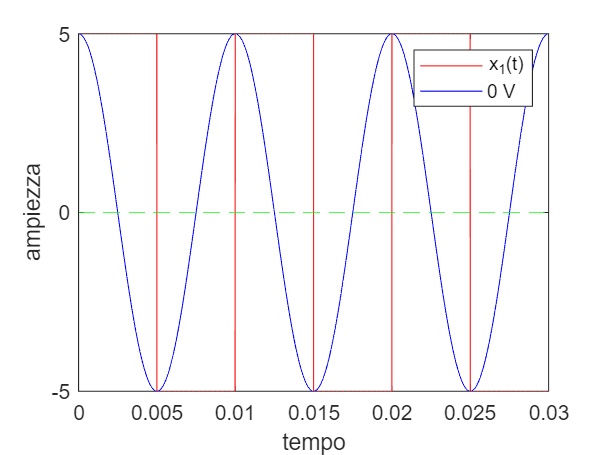

plot(t,x1,'r',t,x1cos,'b')
yline(0,'--g')
xlabel('tempo')
ylabel('ampiezza')
legend('x_1(t)','0 V')


x2 = V0*(-square(2*pi*fx*t))

x2 =     -5
    -5
    -5
    -5
    -5
    -5
    -5
    -5
    -5
    -5


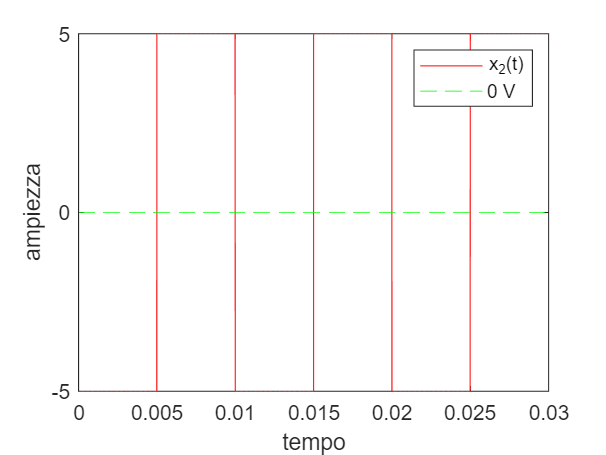

plot(t,x2,'r')
yline(0,'--g')
xlabel('tempo')
ylabel('ampiezza')
legend('x_2(t)','0 V')


x3 = V0*(-square(2*pi*fx*t)/2 + 0.5)

x3 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


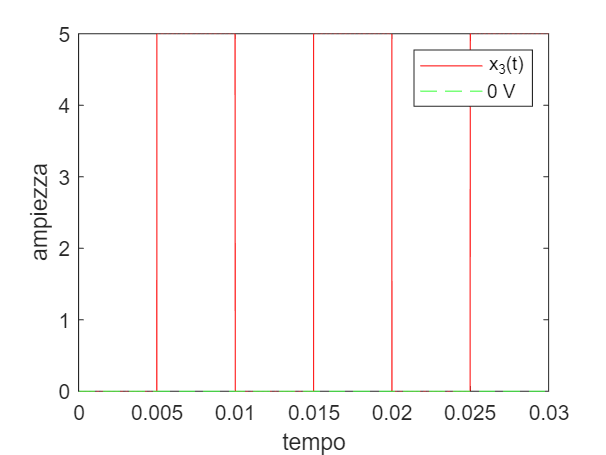

plot(t,x3,'r')
yline(0,'--g')
xlabel('tempo')
ylabel('ampiezza')
legend('x_3(t)','0 V')

## Simulazione di risposta del circuito RC a onda quadra unipolare, con periodo "lungo" o "breve" (rispetto a tau)

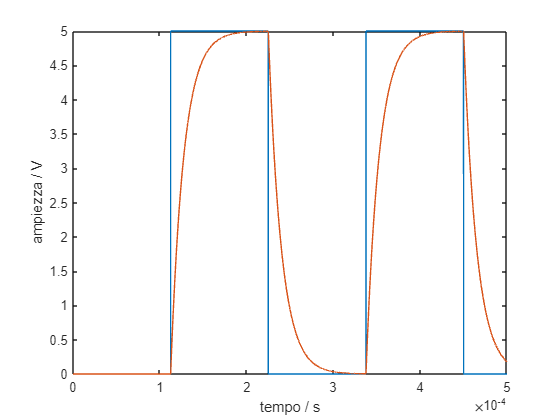

Risposta a onda quadra unipolare con periodo "lungo"

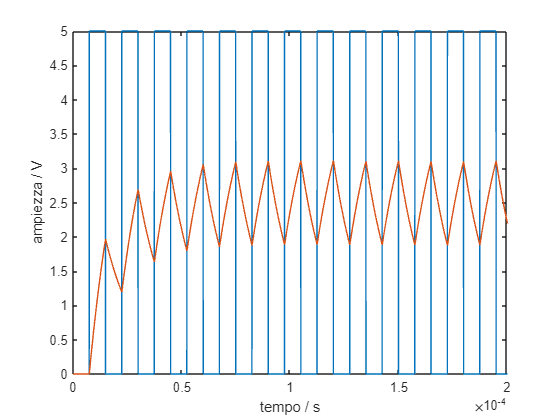

Risposta a onda quadra unipolare con periodo "breve"

% Si simuli la risposta a un'onda quadra unipolare per il circuito RC iniziale
% Generare grafici come quelli in figura

% Dati
% H_tf = funzione di trasferimento del sistema (uguale a quella del quesito iniziale)
% t = vettore colonna di N istanti di tempo equispaziati in [0; Td[
% Tx1 = 15*tau % periodo dell'onda quadra, caso di periodo "lungo"
% Tx2 = tau % periodo dell'onda quadra, caso di periodo "breve"
% V0 = 5 % ampiezza dell'onda quadra (da 0 a V0, valore iniziale = 0)

% Domande
% x1 = onda quadra unipolare con periodo "lungo" Tx1
% x2 = onda quadra unipolare con periodo "breve" Tx2
% y1 = risposta a x1
% y2 = risposta a x2

% Nota
% L'onda quadra deve essere unipolare, con valori tra 0 e V0, e con valore 0 all'istante t = 0

% Codice iniziale
clear
R = 1e2; % resistenza
Rgen = 50; % resistenza generatore
R1 = R+Rgen; % resistenza costante di tempo
C = 100e-9; % capacità
tau = R1*C; % costante di tempo
s = tf('s'); % variabile della trasformata di Laplace
H_tf = 1/(1+s*tau) % funzione di trasferimento

H_tf =
 
        1
  -------------
  1.5e-05 s + 1
 
Continuous-time transfer function.




Td = 50e-5; 
N = 1e5;
Ts = Td/N;
n = (0:N-1)';
t = n*Ts; % istanti di tempo

Tx1 = 15*tau;
Tx2 = tau;
V0 = 5;

### Soluzione

fx1 = 1/Tx1

fx1 = 4.4444e+03

fx2 = 1/Tx2

fx2 = 6.6667e+04

x1 = V0*(-square(2*pi*fx1+t)/2 + 1/2)

x1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y1 = lsim(H_tf,x1,t)

y1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


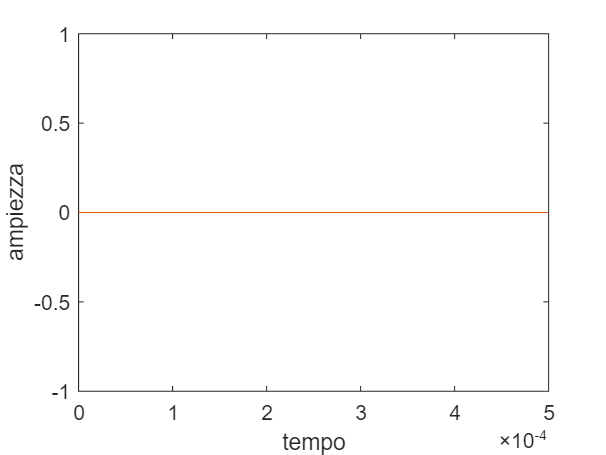

plot(t,x1,t,y1)
xlabel('tempo')
ylabel('ampiezza')

x2 = V0*(-square(2*pi*fx2+t)/2 + 1/2)

x2 =      5
     5
     5
     5
     5
     5
     5
     5
     5
     5


y2 = lsim(H_tf,x2,t)

y2 =          0
    0.0017
    0.0033
    0.0050
    0.0067
    0.0083
    0.0100
    0.0117
    0.0133
    0.0150


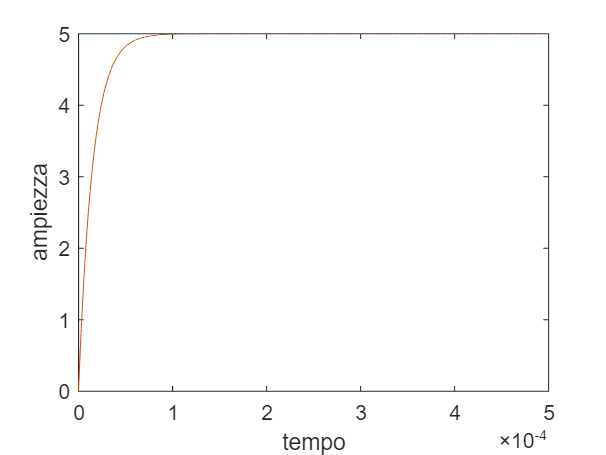

plot(t,x2,t,y2)
xlabel('tempo')
ylabel('ampiezza')

xlim([0,2e-4])

## Simulazione di risposta del circuito RC a onda quadra bipolare, con periodo "lungo" o "breve"

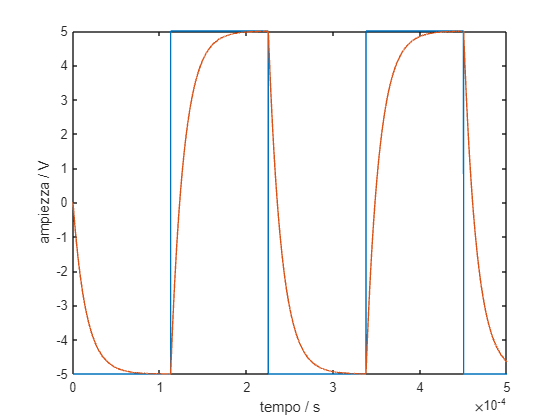

Risposta a onda quadra bipolare con periodo "lungo"

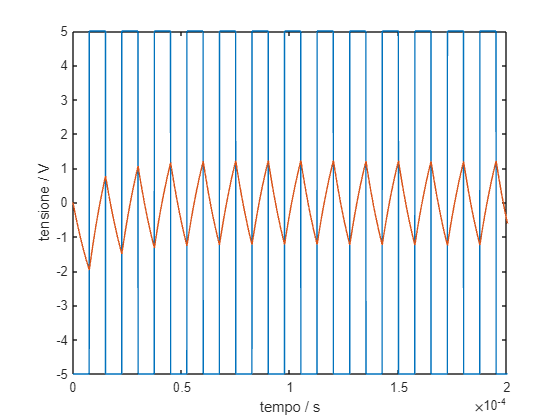

Risposta a onda quadra bipolare con periodo "breve"

% Simulazione di risposta a un'onda quadra bipolare
% Si simuli la risposta a un'onda quadra bipolare per il circuito RC iniziale

% Dati
% Quelli del quesito precedente.

% Domande
% x1 = onda quadra bipolare con periodo "lungo" Tx1
% x2 = onda quadra bipolare con periodo "breve" Tx2
% y1 = risposta a x1
% y2 = risposta a x2

% Nota
% Le onde quadre richieste sono bipolari tra -V0 e V0, con valore iniziale = -V0

### Soluzione

x1 = V0*(-square(2*pi*fx1+t))

x1 =     -5
    -5
    -5
    -5
    -5
    -5
    -5
    -5
    -5
    -5


y1 = lsim(H_tf,x1,t)

y1 =          0
   -0.0017
   -0.0033
   -0.0050
   -0.0067
   -0.0083
   -0.0100
   -0.0117
   -0.0133
   -0.0150


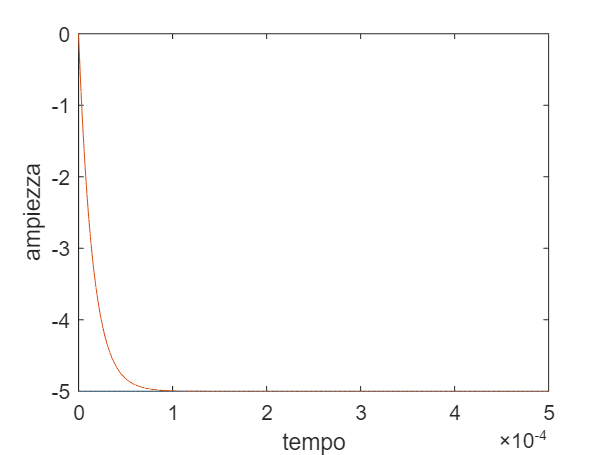

plot(t,x1,t,y1)
xlabel('tempo')
ylabel('ampiezza')

x2 = V0*(-square(2*pi*fx2+t))

x2 =      5
     5
     5
     5
     5
     5
     5
     5
     5
     5


y2 = lsim(H_tf,x2,t)

y2 =          0
    0.0017
    0.0033
    0.0050
    0.0067
    0.0083
    0.0100
    0.0117
    0.0133
    0.0150


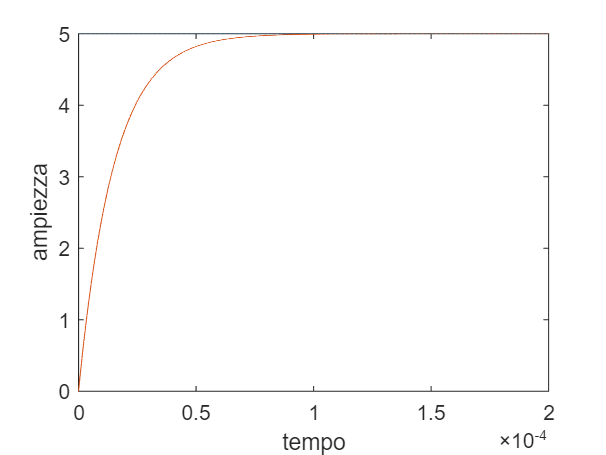

plot(t,x2,t,y2)
xlabel('tempo')
ylabel('ampiezza')
xlim([0,2e-4])

## Misura di capacità da risposta a onda quadra con periodo "breve"

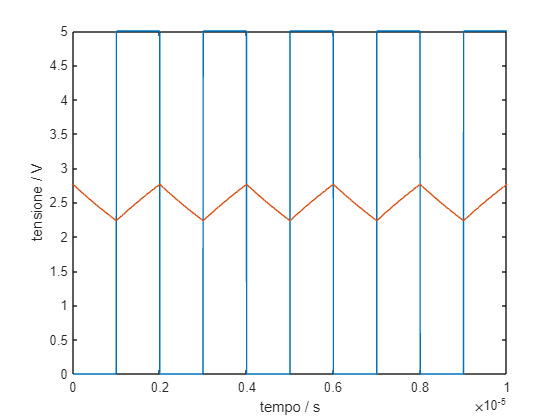

Rsiposta a regime del circuito RC a onda quadra a periodo "breve". La costante di tempo è data dalla formula:


$$\tau =\frac{V_{\textrm{pp},x} /2}{V_{\textrm{pp},y} }\;\frac{T_x }{2}=\frac{V_{\textrm{pp},x} }{V_{\textrm{pp},y} }\;\frac{T_x }{4}$$


sia per onda quadra unipolare, che per onda quadra bipolare.

La formula deriva dal fatto che per periodo breve la risposta è approssimabile a un segnale lineare nel tempo, con pendenza


$$m=\frac{V_{\textrm{pp},x} }{2}\;\frac{1}{\tau \;}$$


% La risposta a onda quadra del circuito precedente è quella in figura. Misurare la capacità.
% Tracciare anche il grafico dato come figura

% Dati
% R = 50 % resistenza nel circuito
% x = % segnale a onda quadra in ingresso
% y = % segnale in uscita
% C0 = % capacità vera

% Domande
% Rgen = resistenza del generatore
% Vppx = tensione picco picco dell'onda quadra in ingresso (x)
% Vppy = tensione picco picco del segnale in uscita (y)
% tau = costante di tempo del circuito
% C = capacità
% er_pc = errore relativo percentuale nella misura di capacità

% Codice iniziale
clear

R = 50; % resistenza
C0 = 47e-9 % capacità

C0 = 4.7000e-08

s = tf('s') % variabile della trasformata di Laplace

s =
 
  s
 
Continuous-time transfer function.



Rgen = 50

Rgen = 50

R1 = R+Rgen

R1 = 100

tau = R1*C0

tau = 4.7000e-06

Tx = 2e-6

Tx = 2.0000e-06

Np = 50

Np = 50

Td = Np*Tx

Td = 1.0000e-04

N = 1e6;
Ts = Td/N

Ts = 1.0000e-10

n = (0:N-1)';
t0 = n*Ts

t0 = 	1.0e+-4 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


H_tf = 1/(1+s*tau)

H_tf =
 
        1
  -------------
  4.7e-06 s + 1
 
Continuous-time transfer function.



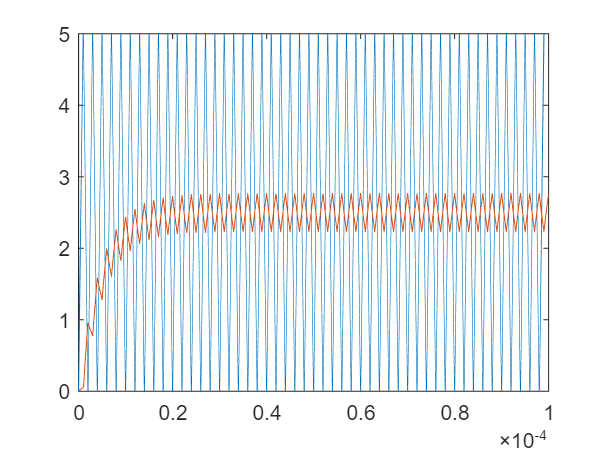

fx = 1/Tx;
V0 = 5;
x0 = V0*(-square(2*pi*fx*t0)/2 + 0.5);
y0 = lsim(H_tf,x0,t0);
plot(t0,x0,t0,y0)


% Calcolo della risposta a regime
x = x0((9/10*N+1):end)

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y = y0((9/10*N+1):end)

y =     2.7647
    2.7647
    2.7646
    2.7645
    2.7645
    2.7644
    2.7644
    2.7643
    2.7642
    2.7642


t = t0(1:N/10)

t = 	1.0e+-5 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0001


### Soluzione

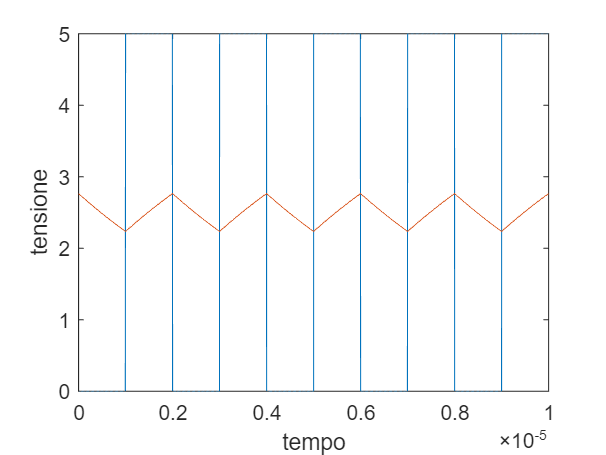

plot(t,x,t,y)
xlabel('tempo')
ylabel('tensione')

Vppx = range(x) %max - min

Vppx = 5

Vppy = range(y)

Vppy = 0.5300

tau = Vppx/Vppy*Tx/4

tau = 4.7171e-06

C = tau/(R+Rgen)

C = 4.7171e-08

er_pc = (C/C0-1)*100

er_pc = 0.3638